# Create Simple Image Classification Network

## Load Data

Download and create the medMNIST image datastore. The `imageDatastore` function automatically labels the images based on folder names.

medmnistdatadata = readmedmnist("derma");

Completed download in 17.2702 seconds. 
Extracting: train_images structure. 
Extracting: train_labels structure. 


save_path = "./dermadataset";
mkdir(save_path);
imds = createmedmnistdatastore(medmnistdatadata.train_images, medmnistdatadata.train_labels, "savepath", save_path);

Divide the data into training and validation data sets, so that each category in the training set contains 80% of the data set, and the validation set contains the remaining images from each label. `splitEachLabel` splits the image datastore into two new datastores for training and validation.

train_proportion = 0.8;
[imdsTrain, imdsValidation] = splitEachLabel(imds, train_proportion, "randomized");

View the class names.

classNames = categories(imdsTrain.Labels)

classNames = 7×1 cell array
    {'0'}
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}


## Define Network Architecture

Define the convolutional neural network architecture. Specify the size of the images in the input layer of the network and the number of classes in the fully connected layer. Each image is 28-by-28-by-3 pixels and there are 7 classes.

inputSize = [28 28 3];
numClasses = numel(classNames);

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer];

## Specify Training Options

Specify the training options. Choosing among the options requires empirical analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](docid:nnet_ref#mw_11ce840f-eed7-4975-9c28-baeebd79f092) app. 

options = trainingOptions("sgdm", ...
    MaxEpochs=4, ...
    ValidationData=imdsValidation, ...
    ValidationFrequency=30, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

## Train Neural Network

Train the neural network using the [`trainnet`](docid:nnet_ref.mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. For classification, use cross-entropy loss. By default, the `trainnet` function uses a GPU if one is available. Using a GPU requires a Parallel Computing Toolbox™ license and a supported GPU device. For information on supported devices, see [GPU Computing Requirements](docid:distcomp_ug.mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Otherwise, the function uses the CPU. To specify the execution environment, use the `ExecutionEnvironment` training option.

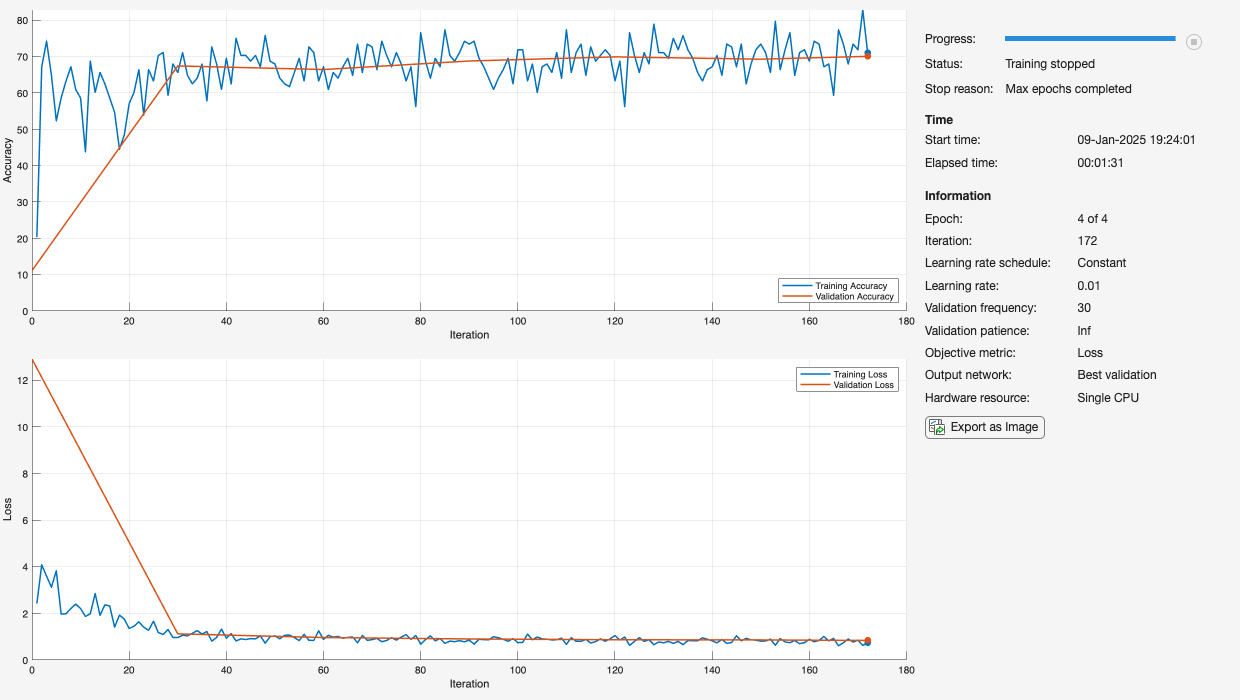

net = trainnet(imdsTrain, layers, "crossentropy", options);

## Test Neural Network

To test the neural network, classify the validation data and calculate the classification accuracy. 

Test the neural network using the [`testnet`](docid:nnet_ref.mw_3eb84788-36da-4e3e-a351-ecbc55b86c2b) function. For single-label classification, evaluate the accuracy. The accuracy is the percentage of correct predictions. By default, the `testnet` function uses a GPU if one is available. To select the execution environment manually, use the `ExecutionEnvironment` argument of the `testnet` function.

accuracy = testnet(net, imdsValidation, "accuracy")

accuracy = 70.0641